## **Task 3**

fprintf("----------------------Task3---------------------")

----------------------Task3---------------------

% 3.a. the probability of the link being in each of the five states
in_states = [8, 5, 2, 1]; % like birth states
out_states = [600, 100, 20 , 5]; % like death states

x = [in_states(1), in_states(1)*in_states(2), in_states(1)*in_states(2)*in_states(3), in_states(1)*in_states(2)*in_states(3)*in_states(4)];
y = [out_states(1), out_states(1)*out_states(2), out_states(1)*out_states(2)*out_states(3), out_states(1)*out_states(2)*out_states(3)*out_states(4)];

pi0 = 1/(1+sum(x./y));
pi1 = pi0*sum(x(1)./y(1));
pi2 = pi0*sum(x(2)./y(2));
pi3 = pi0*sum(x(3)./y(3));
pi4 = pi0*sum(x(4)./y(4));
fprintf("\nThe probability of the link being in each of the five states\n");


The probability of the link being in each of the five states


fprintf("%.2e (State 10^-6)\n", pi0);

9.86e-01 (State 10^-6)


fprintf("%.2e (State 10^-5)\n", pi1);

1.31e-02 (State 10^-5)


fprintf("%.2e (State 10^-4)\n", pi2);

6.57e-04 (State 10^-4)


fprintf("%.2e (State 10^-3)\n", pi3);

6.57e-05 (State 10^-3)


fprintf("%.2e (State 10^-2)\n", pi4);

1.31e-05 (State 10^-2)


%3.b. the average percentage of time the link is in each of the five states
%%% The avg is the same as 3.a
fprintf("The average percentage of time the link is in each of the five states\n");

The average percentage of time the link is in each of the five states


fprintf("%.2e (State 10^-6)\n", pi0);

9.86e-01 (State 10^-6)


fprintf("%.2e (State 10^-5)\n", pi1);

1.31e-02 (State 10^-5)


fprintf("%.2e (State 10^-4)\n", pi2);

6.57e-04 (State 10^-4)


fprintf("%.2e (State 10^-3)\n", pi3);

6.57e-05 (State 10^-3)


fprintf("%.2e (State 10^-2)\n", pi4);

1.31e-05 (State 10^-2)


%3.c. the average ber of the link
avg_ber_link = (10^-6)*pi0 + (10^-5)*pi1 + (10^-4)*pi2 + (10^-3)*pi3 + (10^-2)*pi4;
fprintf("The average ber of the link is: %.2e\n", avg_ber_link);

The average ber of the link is: 1.38e-06


%3.d. the average time duration (in minutes) that the link stays in each of the five states;
m = [0 600 0 0 0;
     8 0 100 0 0;
     0 5 0 20 0;
     0 0 2 0 5;
     0 0 0 1 0];
t00 = (1 / sum(m(:,1)))*60;
t01 = (1 / sum(m(:,2)))*60;
t02 = (1 / sum(m(:,3)))*60;
t03 = (1 / sum(m(:,4)))*60;
t04 = (1 / sum(m(:,5)))*60;

fprintf("Average time duration that the link stays in each state\n")

Average time duration that the link stays in each state


fprintf("Estado 10^-6: %1.2f minutos\n", t00);

Estado 10^-6: 7.50 minutos


fprintf("Estado 10^-5: %1.2f minutos\n", t01);

Estado 10^-5: 0.10 minutos


fprintf("Estado 10^-4: %1.2f minutos\n", t02);

Estado 10^-4: 0.59 minutos


fprintf("Estado 10^-3: %1.2f minutos\n", t03);

Estado 10^-3: 2.86 minutos


fprintf("Estado 10^-2: %1.2f minutos\n\n", t04);

Estado 10^-2: 12.00 minutos



%3.e. the probability of the link being in the normal state and in interference state
p_interf = pi3 + pi4;
p_normal = pi0 + pi1 + pi2;

fprintf("The probability (normal state) is:%.6f\n", p_normal);

The probability (normal state) is:0.999921


fprintf("The probability (interference state) is:%.2e\n", p_interf);

The probability (interference state) is:7.89e-05


%3.f. the average ber of the link when it is in the normal state and when it is in the interference
ber_normal = ((10^-6)*pi0 + (10^-5)*pi1 + (10^-4)*pi2)/p_normal;
ber_interf = ((10^-3)*pi3 + (10^-2)*pi4)/p_interf;
fprintf("The avg BER (normal state) is:%.2e\n",ber_normal);

The avg BER (normal state) is:1.18e-06


fprintf("The avg BER (interference state) is:%.2e\n", ber_interf);

The avg BER (interference state) is:2.50e-03


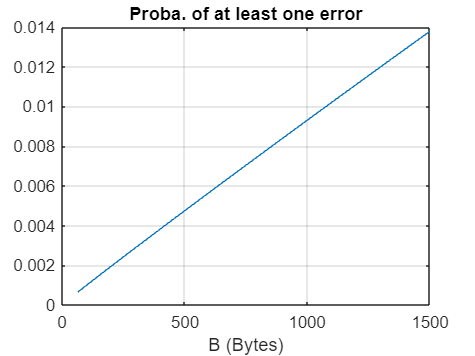

%3.g. draw a plot with the same look as the plot below of the probability of the packet 
%being received by the destination station with at least one error as a function of the packet 
%size (from 64 Bytes up to 1500 Bytes)

dataFrameSize = 64:1500; % data frame size
prob = zeros(1, length(dataFrameSize));
perr_1 = zeros(1, length(dataFrameSize));
perr_2 = zeros(1, length(dataFrameSize));
perr_3 = zeros(1, length(dataFrameSize));
perr_4 = zeros(1, length(dataFrameSize));
perr_5 = zeros(1, length(dataFrameSize));

for i=1:length(dataFrameSize)
    perr_1(i) =  1 - (( nchoosek(dataFrameSize(i)*8 , 0) * (10^-6)^0 * (1-(10^-6))^(dataFrameSize(i)*8 - 0) ));
    perr_2(i) = 1 - (( nchoosek(dataFrameSize(i)*8 , 0) * (10^-5)^0 * (1-(10^-5))^(dataFrameSize(i)*8 - 0) ));
    perr_3(i) = 1 - (( nchoosek(dataFrameSize(i)*8 , 0) * (10^-4)^0 * (1-(10^-4))^(dataFrameSize(i)*8 - 0) ));
    perr_4(i) = 1 - (( nchoosek(dataFrameSize(i)*8 , 0) * (10^-3)^0 * (1-(10^-3))^(dataFrameSize(i)*8 - 0) ));
    perr_5(i) = 1 - (( nchoosek(dataFrameSize(i)*8 , 0) * (10^-2)^0 * (1-(10^-2))^(dataFrameSize(i)*8 - 0) ));
    prob(i) = perr_1(i)*pi0 + perr_2(i)*pi1 + perr_3(i)*pi2 + perr_4(i)*pi3 + perr_5(i)*pi4;
end

figure(1)
plot(dataFrameSize, prob);
axis([0 1500 0 0.014]);
xlabel("B (Bytes)");
title("Proba. of at least one error");
grid on


%conclusão: quanto mais pacotes tivermos, maior probalidade ter-se-a de 
%de recepção de erros.

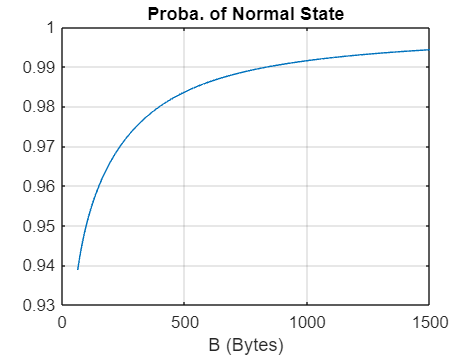

%3.h.draw a plot with the same look as the 
%plot below of the probability of the link being in the normal state as a function of the 
%packet size (from 64 Bytes up to 1500 Bytes)

perrs_1 = 1 - (1- 10^-6).^(dataFrameSize.*8);
perrs_2 = 1 - (1- 10^-5).^(dataFrameSize.*8);
perrs_3 = 1 - (1- 10^-4).^(dataFrameSize.*8);
perrs_4 = 1 - (1- 10^-3).^(dataFrameSize.*8);
perrs_5 = 1 - (1- 10^-2).^(dataFrameSize.*8);

p_normal_plot = (perrs_1.*pi0 + perrs_2.*pi1 + perrs_3.*pi2)./(perrs_1.*pi0+perrs_2.*pi1+perrs_3.*pi2+perrs_4.*pi3+perrs_5.*pi4);
figure(2)
plot(dataFrameSize, p_normal_plot);
axis([0 1500 0.93 1]);
xlabel("B (Bytes)");
title("Proba. of Normal State");
grid on

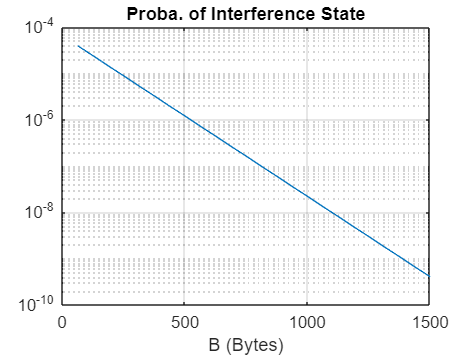

%3.i. draw a plot with the same look as the plot below 
%(use the MATLAB function semilogy) of the probability of the link being in the 
%interference state as a function of the packet size (from 64 Bytes up to 1500 Bytes);
%analyze and justify the results
pnei_1 = (1- 10^-6).^(dataFrameSize.*8); % pnei: probality to have no error when we have interference
pnei_2 = (1- 10^-5).^(dataFrameSize.*8);
pnei_3 = (1- 10^-4).^(dataFrameSize.*8);
pnei_4 = (1- 10^-3).^(dataFrameSize.*8);
pnei_5 = (1- 10^-2).^(dataFrameSize.*8);

p_interference_plot = (pnei_4.*pi3 + pnei_5.*pi4)./(pnei_1.*pi0+pnei_2.*pi1+pnei_3.*pi2+pnei_4.*pi3+pnei_5.*pi4);

figure(3)
semilogy(dataFrameSize, p_interference_plot);
axis([0 1500 10^-10 10^-4]);
xlabel("B (Bytes)");
title("Proba. of Interference State");
grid on

## **Task 4**

fprintf("----------------------Task4---------------------")

----------------------Task4---------------------

%4.a. the average packet size (in Bytes) and the average packet transmission time of the IP flow
% rember about Poison rules process
C = 10; % capacity of the link (in Mbps-megabits per second)
Y = 1000; % flow to arrive new clients(in packet per second-pps)

n = (109 - 65 + 1) + (1517 - 111 + 1); % number of elements or packets - size of the packets in bytes
p1 = 100 - (19 + 23 + 17); % probability of remaining packets or elements
p2 = p1/n ;% probability of each packet

a = 65:109;
a = a*(p2/100);
b = 111:1517;
b = b*(p2/100);

avg_s = 0.19*64 + 0.23*110 + 0.17*1518 + sum(a) + sum(b); % average packet size
avg_t = (avg_s*8)/(C*10^6); % average packet transmission time

fprintf("Avarage packet size: %.2f Bytes\n", avg_s);

Avarage packet size: 620.02 Bytes


fprintf("Avarage transmission time: %.2e seconds\n", avg_t);

Avarage transmission time: 4.96e-04 seconds


%4.b. the average throughput (in Mbps) of the IP flow

avg_throughput = Y * (avg_s/125000);
fprintf("Avarage throughput: %.2f Mbps\n", avg_throughput);

Avarage throughput: 4.96 Mbps


%4.c. the capacity of the link, in pps

C_link = C/(avg_s/125000);
fprintf("Capacity of the link: %.2f pps\n", C_link);

Capacity of the link: 2016.06 pps


%4.d. the average packet queuing delay and packet system delay of the IP flow (the system 
%delay is the queuing delay + transmission time + propagation delays)

pkt_size = 64:1518; % in bytes
S = (pkt_size.*8)./(C*10^6); % server attendance time
S2 = (pkt_size.*8)./(C*10^6); % server attendance time for second moment

for i = 1:length(pkt_size)
    if i == 1
        S(i) = S(i)*0.19;
        S2(i) = S2(i)^2*0.19;
    elseif i == 110-64+1
        S(i) = S(i)*0.23;
        S2(i) = S2(i)^2*0.23;
    elseif i == 1518-64+1
        S(i) = S(i)*0.17;
        S2(i) = S2(i)^2*0.17;
    else
        S(i) = S(i)*(p2/100); % p2 is the prob for each pkt
        S2(i) = S2(i)^2*(p2/100);
    end
end

ES = sum(S); % the avarage  
ES2 = sum(S2); % the avg of second moment

propagation_delay = 10*10^-6;
avg_q_delay = Y*ES2/(2*(1-Y*ES)); %average packet queuing
pkt_s_delay = avg_q_delay+avg_t+propagation_delay;  %packet system delay

fprintf("Avg queuing delay: %.2e seconds\nSystem packet delay: %.2e seconds\n\n", avg_q_delay, pkt_s_delay);

Avg queuing delay: 4.60e-04 seconds
System packet delay: 9.66e-04 seconds



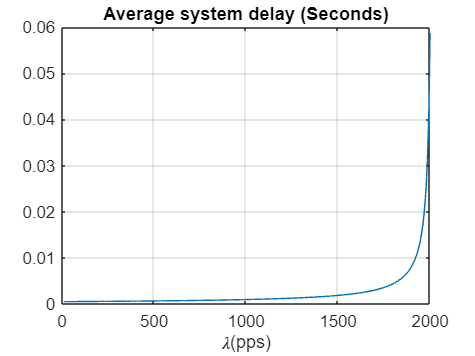

%4.e. draw a plot, knowing that C=10Mbps, lambda=100 pps up to 2000 pps

lambdas = 10:2000; % package arrival rate

avg_q_delay_1 = lambdas.*ES2./(2*(1-lambdas*ES));
pkt_s_delay_1 = avg_q_delay_1+avg_t+propagation_delay;

figure(4)
plot(lambdas, pkt_s_delay_1);
xlabel("{\lambda}(pps)");
title("Average system delay (Seconds)");
grid on

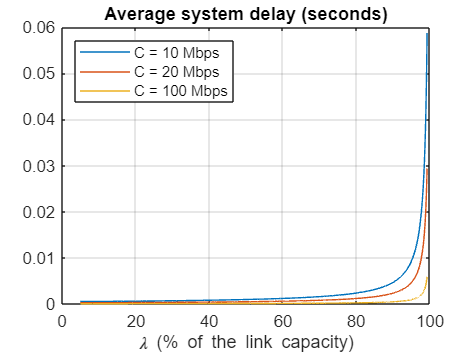

%4.f. draw a plot, knowing that C=10, 20, 100 Mbps, lambda1=100->2000 pps,
%lambda2=200->4000 pps,
%lambda3=1000->20000 pps


lambdas_1 = 100:2000; % package arrival rate
lambdas_2 = 200:4000; % package arrival rate
lambdas_3 = 1000:20000; % package arrival rate

C1 = 10; %  capacity of the link - Mbps
C2 = 20; % capacity of the link - Mbps
C3 = 100; % capacity of the link - Mbps

x1 = (lambdas_1 ./ (C1 /  (avg_s / 125000)))*100;
x2 = (lambdas_2 ./ (C2 /  (avg_s / 125000)))*100;
x3 = (lambdas_3 ./ (C3 /  (avg_s / 125000)))*100;

S1 = (pkt_size .* 8)./(C1*10^6);
S12 = (pkt_size .* 8)./(C1*10^6);
S2 = (pkt_size .* 8)./(C2*10^6);
S22 = (pkt_size .* 8)./(C2*10^6);
S3 = (pkt_size .* 8)./(C3*10^6);
S32 = (pkt_size .* 8)./(C3*10^6);


for i = 1:length(pkt_size)
    if i == 1
        S1(i) = S1(i)*0.19;
        S12(i) = S12(i)^2*0.19;
        S2(i) = S2(i)*0.19;
        S22(i) = S22(i)^2*0.19;
        S3(i) = S3(i)*0.19;
        S32(i) = S32(i)^2*0.19;
    elseif i == 110-64+1
        S1(i) = S1(i)*0.23;
        S12(i) = S12(i)^2*0.23;
        S2(i) = S2(i)*0.23;
        S22(i) = S22(i)^2*0.23;
        S3(i) = S3(i)*0.23;
        S32(i) = S32(i)^2*0.23;
    elseif i == 1518-64+1
        S1(i) = S1(i)*0.17;
        S12(i) = S12(i)^2*0.17;
        S2(i) = S2(i)*0.17;
        S22(i) = S22(i)^2*0.17;
        S3(i) = S3(i)*0.17;
        S32(i) = S32(i)^2*0.17;
    else
        S1(i) = S1(i)*(p2/100);
        S12(i) = S12(i)^2*(p2/100);
        S2(i) = S2(i)*(p2/100);
        S22(i) = S22(i)^2*(p2/100);
        S3(i) = S3(i)*(p2/100);
        S32(i) = S32(i)^2*(p2/100);
    end
end

Q1 = lambdas_1.*sum(S12) ./ (2*(1-lambdas_1.*sum(S1)));
Q2 = lambdas_2.*sum(S22) ./ (2*(1-lambdas_2.*sum(S2)));
Q3 = lambdas_3.*sum(S32) ./ (2*(1-lambdas_3.*sum(S3)));

tmp1 = (avg_s * 8) / (C1*10^6);
tmp2 = (avg_s * 8) / (C2*10^6);
tmp3 = (avg_s * 8) / (C3*10^6);

system1 = Q1 + tmp1 + propagation_delay;
system2 = Q2 + tmp2 + propagation_delay;
system3 = Q3 + tmp3 + propagation_delay;

figure(5);
plot(x1, system1, x2, system2, x3, system3);
title("Average system delay (seconds)");
xlabel("{\lambda} (% of the link capacity)");
legend({'C = 10 Mbps','C = 20 Mbps', 'C = 100 Mbps'},'Location','northwest')
axis([0 100 0 0.06]);
grid on;